# Lab 4 Extension

Simhon, Ryan L, Austin, Justin, Eric Z

## Declare Constants and Sim Values

clear all;

syms Xx Yy Zz mu R angle1 angle2 x I t;

%constants
mu = 4*pi*10^(-7);          %vacuum permeability constant
R = 0.069;                  %radius of the solenoid in m
I1 = 0.215;                  %current through solenoid in A
I2 = 0.225;
N = 320;                    %number of windings
H = 0.0191;                 %width of coil in m
const1 = mu*I1/(4*pi);      %multiplication constant for B-field
const2 = mu*I2/(4*pi);

%important sim characteristics
numpoints = 20*N;
simrange = 0.3;             %limit of sim dimensions
simdensity = simrange/4;    %how many points per sim in 1 dimension (total points ~simdensity^3)
quiverdensity = 8;          %step between subsequent quiver displays (bigger = less dense)
quiverscale = 0.01;        %mag of quivers

%used for finding the correct component in a matrix
uniti = [1, 0, 0];
unitj = [0, 1, 0];
unitk = [0, 0, 1];

## Create Solenoids

%initial positions (m)
s01 = [0, 0, 0];
s02 = [0.12, 0.03, 0.01];

%initial angles (rad)
angle1 = [0, 0, 0] *pi/180;
angle2 = [0, 69, 0] *pi/180;

%create helixes in 3d by the matrix [t, sint, cost]
t1 = linspace(0, N*pi, numpoints);         %solenoid 1
st1 = R*sin(t1);
ct1 = R*cos(t1);
t1 = H*t1/(N*pi);
s1 = [t1; st1; ct1];

t2 = linspace(0, N*pi, numpoints);          %solenoid 2
st2 = R*sin(t2);
ct2 = R*cos(t2);
t2 = H*t2/(N*pi);
s2 = [t2; st2; ct2];

%rotation matrix of solenoid1 
RM_x1 = [1, 0, 0;                               0, cos(angle1(1)), -sin(angle1(1));     0, sin(angle1(1)), cos(angle1(1))];
RM_y1 = [cos(angle1(2)), 0, sin(angle1(2));     0, 1, 0;                                -sin(angle1(2)), 0, cos(angle1(2))];
RM_z1 = [cos(angle1(3)), -sin(angle1(3)), 0;    sin(angle1(3)), cos(angle1(3)), 0;      0, 0, 1];
%rotation matrix of solenoid2
RM_x2 = [1, 0, 0;                               0, cos(angle2(1)), -sin(angle2(1));     0, sin(angle2(1)), cos(angle2(1))];
RM_y2 = [cos(angle2(2)), 0, sin(angle2(2));     0, 1, 0;                                -sin(angle2(2)), 0, cos(angle2(2))];
RM_z2 = [cos(angle2(3)), -sin(angle2(3)), 0;    sin(angle2(3)), cos(angle2(3)), 0;      0, 0, 1];

%rotate the solenoids and shift them on god
totalrotation1 = RM_x1*RM_y1*RM_z1;
totalrotation2 = RM_x2*RM_y2*RM_z2;
s1 = totalrotation1*s1 + transpose(s01);
s2 = totalrotation2*s2 + transpose(s02);

## Calculate B-Field

% %use Biot-Savart formula where dB = const * (ds x r)/r^3
% %where ds = R*dtheta
% 
% B = zeros(3,(simrange/simdensity)^3);
% P = zeros(3,(simrange/simdensity)^3);
% 
% h = waitbar(0,'my nibbas like golden state inbound pull up and shoot');
% n=1;
% for i = 1:simrange/simdensity
%     for j = 1:simrange/simdensity
%         for k = 1:simrange/simdensity
%             P(:,n) = [i * simdensity - simrange/2; j * simdensity - simrange/2; k * simdensity - simrange/2];
% 
%             for t = 1:(numpoints-1)                
%                 r1 = [P(1,n) - s1(1,t); P(2,n) - s1(2,t); P(3,n) - s1(3,t)];
%                 r2 = [P(1,n) - s2(1,t); P(2,n) - s2(2,t); P(3,n) - s2(3,t)];
%                 ds1 = s1(:,t+1) - s1(:,t);
%                 ds2 = s2(:,t+1) - s2(:,t);
%                 
%                 B(:,n) = B(:,n) + const * cross(ds1,r1) / norm(r1)^3 + const * cross(ds2,r2) / norm(r2)^3;
%             end
%             n=n+1;
%         end
%         waitbar(i/simrange*simdensity,h);
%     end
% end
% delete(h); %delete progress bar

## Graph B-Field

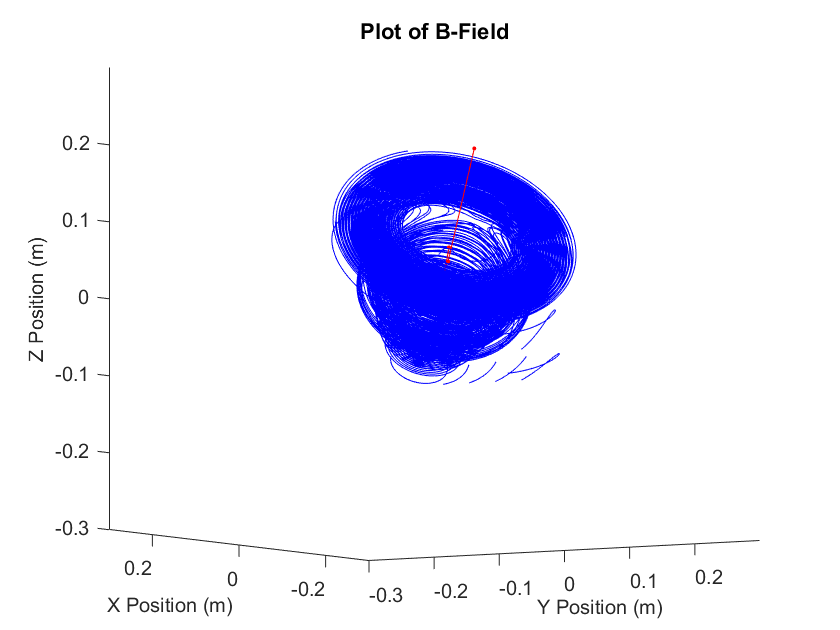

hold on
%plot solenoids
%plot3(s1(1,:), s1(2,:), s1(3,:), 'LineWidth', 1.5, 'Color', 'r');
%plot3(s2(1,:), s2(2,:), s2(3,:), 'LineWidth', 1.5, 'Color', 'r');

dGamma = 0.01; % filament max discretization step [m]
BSmag.Nfilament=0;
[BSmag] = BSmag_add_filament(BSmag,s1,I1,dGamma); %the two filaments
[BSmag] = BSmag_add_filament(BSmag,s2,I2,dGamma); %times 1e4 for current because we use centimetre scale, B varies with 1/(r^2)

% Field points (where we want to calculate the field)
x_M = linspace(-0.1,0.2,25);
y_M = linspace(-0.1,0.2,25);
z_M = linspace(-0.1,0.2,35);
[X_M,Y_M,Z_M]=meshgrid(x_M,y_M,z_M);

% Biot-Savart Integration
[BSmag,X,Y,Z,BX,BY,BZ] = BSmag_get_B(BSmag,X_M,Y_M,Z_M);

% Plot B
normB=sqrt(BX.^2+BY.^2+BZ.^2);
[X0,Y0,Z0] = ndgrid(-0.05,-0.1:0.04:0.1,-0.1:0.04:0.1); % define tubes starting point        
%quiver3(X,Y,Z,BX./normB,BY./normB,BZ./normB)
streamline(X_M,Y_M,Z_M,BX./normB,BY./normB,BZ./normB, X0, Y0, Z0);

%Add title and labels to axis
title('Plot of B-Field');
xlabel('X Position (m)', 'FontSize', 10);
ylabel('Y Position (m)', 'FontSize', 10);
zlabel('Z Position (m)', 'FontSize', 10);
xlim([-0.3 0.3]);
ylim([-0.3 0.3]);
zlim([-0.3 0.3]);
view(-35,45);